# Numerical Methods for Optimization and Control Theory

## Assignment 1 - Daniel Kuknyo

Tasks assigned: 2, 5, 7, 13

## 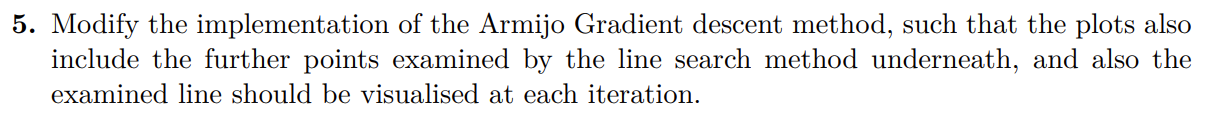

## Define the function

% Rosenbrock function
rr = [-1.0 1.2 -0.2 1.2];
startpt = [0; 1];
f=@(x) 100.*(x(2)-x(1).^2).^2+(1-x(1)).^2;
df=@(x) [400.*x(1).^3-400.*x(1).*x(2)+2.*x(1)-2;200.*(x(2)-x(1).^2)];
ddf=@(x) [1200.*x(1).^2-400.*x(2)+2 -400.*x(1);-400.*x(1) 200];

## Plot the Rosenbrock function

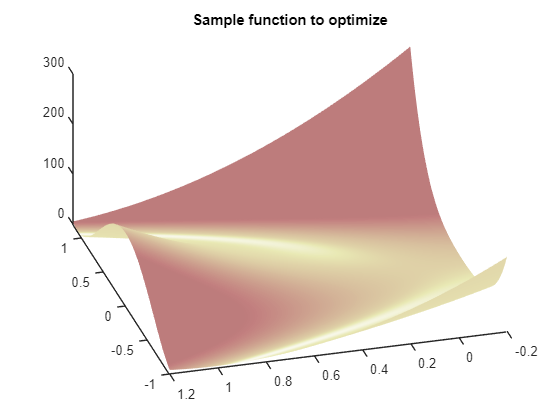

a = rr(1);
b = rr(2);
c = rr(3);
d = rr(4);
res = 256;

X = linspace(a,b,res);
Y = linspace(c,d,res);
[X,Y] = meshgrid(X,Y);
Z = zeros(res,res);

for i=1:res
    for j=1:res
        Z(i,j) = f([X(i,j),Y(i,j)]);
    end
end

figure; hold on;
surfl(X,Y,Z);
colormap("pink");
shading interp;
title("Sample function to optimize");
view([-106 46]);
hold off;

## Let's plot!

On the following diagram you can see the Gradient Descent points in red, Armijo LS points in green and the lines inspected by the algorithm with blue. 

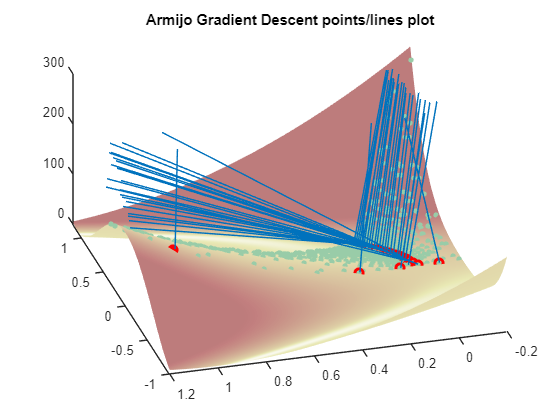

plot_Armijo_GD(@grad_descent, f, df, ddf, 50, ...
    startpt, rr(1), rr(2), rr(3), rr(4), 256, [-106 46]);

## A different viewing angle

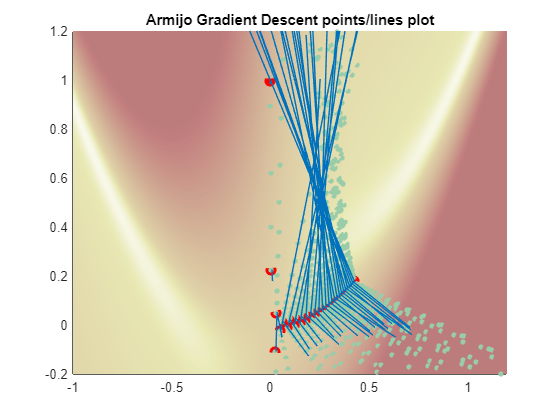

plot_Armijo_GD(@grad_descent, f, df, ddf, 50, ...
    startpt, rr(1), rr(2), rr(3), rr(4), 256, [0 90]);

## Functions

function [ x ] = plot_Armijo_GD(G, f, df, ddf, testpts, startpt, a, b, c, d, res, viewAngle) 
    % Get the general function
    w = 0;
    v = 300;
    X = linspace(a,b,res);
    Y = linspace(c,d,res);
    [X,Y] = meshgrid(X,Y);
    Z = zeros(res,res);
    
    for i=1:res
        for j=1:res
            Z(i,j) = f([X(i,j), Y(i,j)]);
        end
    end

    % x->points of GD, pts->points of Amijo LS, lns->Lines of Armijo
    [x, pts, lns] = grad_descent(f, df, 0, startpt, testpts);

    % Plot
    figure;
    hold on;

    % Plot the surface
    surfl(X,Y,Z);

    % Plot the GD points
    for i=1:size(x, 2)
        px = x(1, i);
        py = x(2, i);
        pz = f([px, py]);
        if(~isOutofBounds(a,b,c,d,[px;py;pz]))
            plot3(px, py, pz,  '.', ...
                'MarkerSize', 25, ...
                'MarkerEdgeColor', 'red', ...
                'MarkerFaceColor', [1 .6 .6]);
        end
    end

    % Plot the Armijo points
    for i=1:size(pts, 2)
        px = pts(1, i);
        py = pts(2, i);
        pz = pts(3, i);
        if(~isOutofBounds(a,b,c,d,[px;py;pz]))
            plot3(px, py, pz,  '.', ...
                'MarkerSize', 12, ...
                'MarkerEdgeColor', [.6 .8 .66], ...
                "MarkerFaceColor", [.38 .51 .31]);
        end
    end
   
    % Plot the Armijo lines
    x(:, end) = [];
    for i=1:size(lns, 2)
        px = x(1, i);
        py = x(2, i);
        pz = f([py, py]);
        pt = [px, py, pz];

        lx = lns(1, i);
        ly = lns(2, i);
        lz = f([lx, ly]);
        lt = [lx, ly, lz];

        pconn = [pt; lt];
        pconn = [lt; pt];
        line(pconn(:,1), pconn(:,2), pconn(:,3));
    end

    % Settings for the plot
    colormap("pink");
    shading interp;
    title("Armijo Gradient Descent points/lines plot");
    view(viewAngle);
    xlim([a b]);
    ylim([c d]);
    zlim([w v]);
    hold off;
end

% Is a point out of the bounds? 1 -> we don't plot it (aesthetic purposes)
function isOut = isOutofBounds(a, b, c, d, x)
    isOut = false;
    if(x(1)<a | x(1)>b | x(2)<c | x(2)>d | x(3)>300 | x(3)<0)
        isOut = true;
    end
end

function [x, pts, lns] = grad_descent(f, df, ~, x0, iter)
    rho = 0.8; 
    c = 0.2; 
    alpha = 1;
    x_k = x0; % Starting point
    x = [x0]; % Points of Gradient Descent
    lns = [];
    pts = [];

    for k = 1:iter
        p = -df(x_k); % Direction of (steepest) descent
        [gamma, pts_k] = Armijo_LS(f, df, p, x_k, alpha, rho, c); % Step length
        x_k = x_k + gamma*p;
        x = [x x_k];
        lns = [lns p]; % These lines will be plotted
        pts = [pts pts_k];
    end
end

function [alpha, pts_k] = Armijo_LS(f, df, p, x0, alpha, rho, c)
    f0 = f(x0);
    g0 = df(x0);
    x = x0 + alpha .* p;
    fk = f(x);
    dp = (g0'*p);
    pts_k = [];

    while fk < f0 + c * alpha * dp
      alpha = alpha / rho;
      x = x0 + alpha * p;
      fk = f(x);
      fxk = [x; fk];
      pts_k = [pts_k fxk];
    end
    while fk > f0 + c * alpha * dp
      alpha = rho * alpha;
      x = x0 + alpha * p;
      fk = f(x);
      fxk = [x; fk];
      pts_k = [pts_k fxk];
    end
end